# Meshes

## Creating a mesh

A mesh consists of a list of vertex coordinates and a list of triangle indices

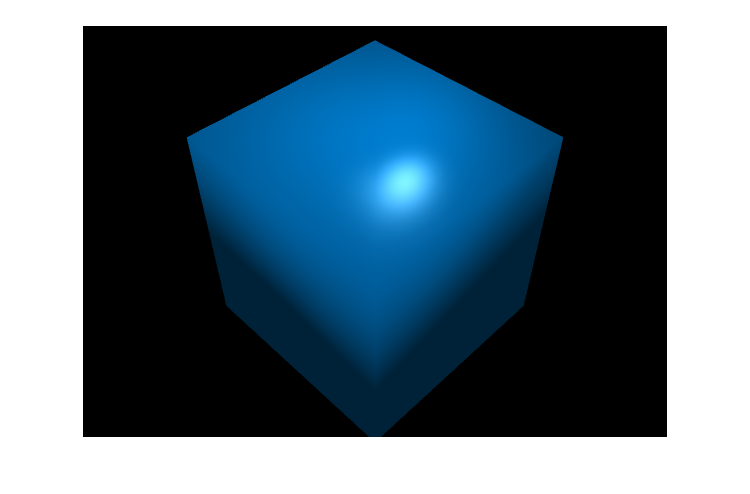

f = fvclear;

[coords,tri] = cubemesh;

fvMesh(tri,coords);
f.Camera.Translation(3) = -3;
f.Snapshot;

## Mesh without vertex normals

Normals are automatically calculated to render a smooth mesh, you can deactivate it

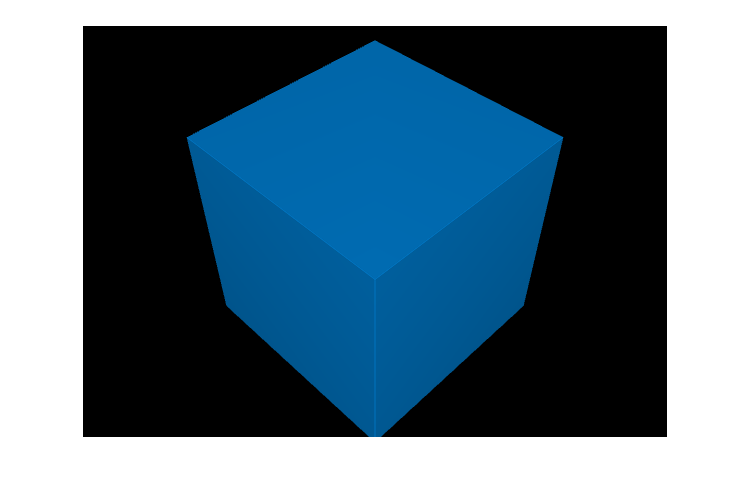

m = fvMesh(tri,coords,'AutoCalcNormals',false);
f.Camera.Translation(3) = -3;
f.Snapshot;

## Cull front faces

Set to 1 to Cull front face or 0 to disable culling

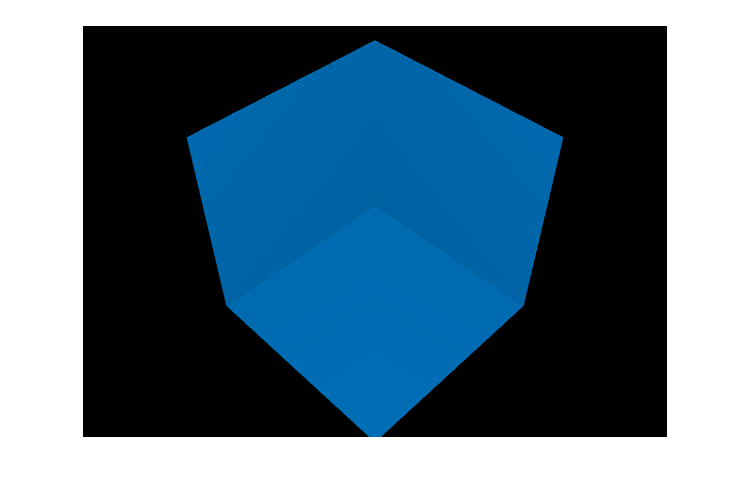

m.Cull = -1;
f.Snapshot;

## Show only first 6 triangles

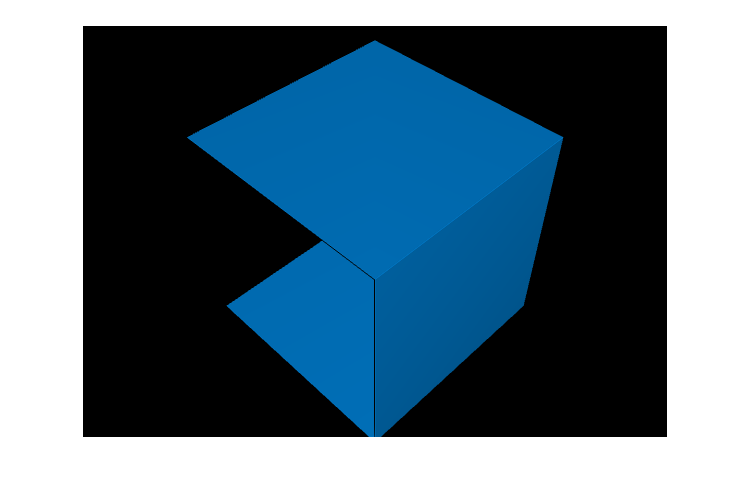

m.Cull = 0;
m.Index = m.Index(1:6,:);
f.Snapshot;

## Show a more complex mesh

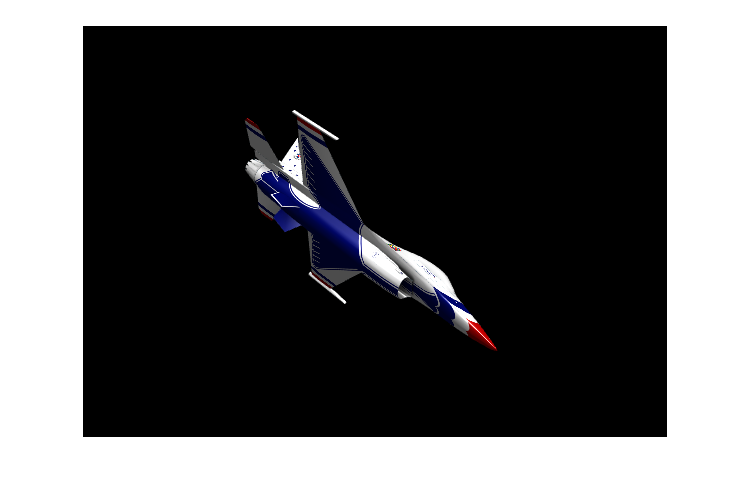

wo = wobj('f16.obj');
[tri,xyz,texCoord,normals,materials,vertex_material] = wo.getDrawData;

m = fvMesh(tri,xyz,texCoord,normals,materials,vertex_material);
f.Snapshot;

## Rotate it to make it upright

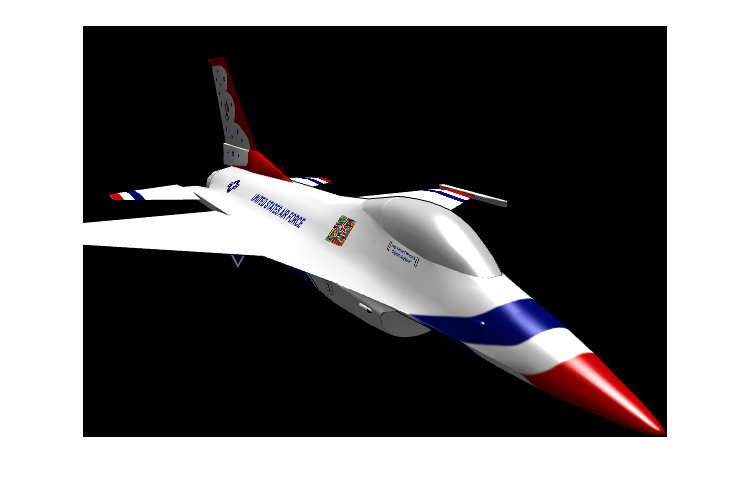

m.Rotate([90 0 0],true);
f.Camera.Translation(3) = -2;
f.Camera.Rotation = [-76.6000         0  -62.0000];
f.Snapshot;

## Make the window black and transparent

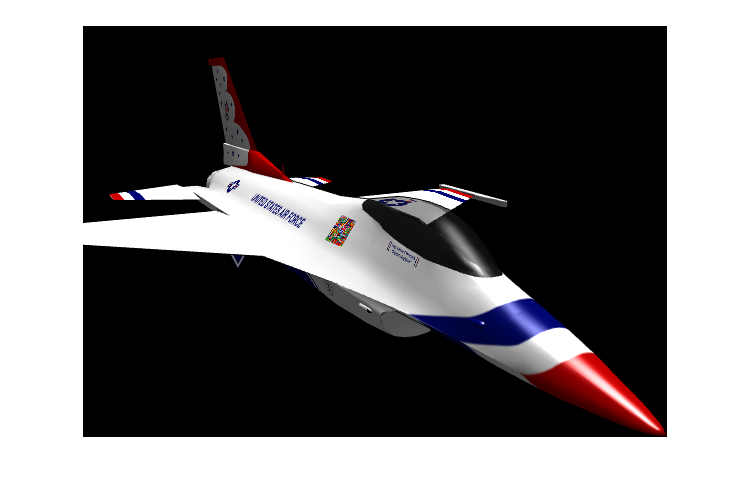

m.Material(2).Color = [0.1 0.1 0.1];
m.Material(2).Alpha = 0.5;
f.Snapshot;

## Change a texture

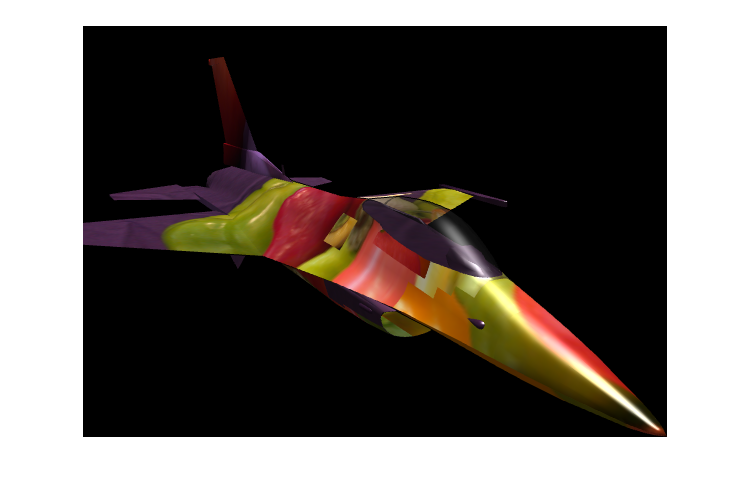

m.Material(1).Color = 'peppers.png';
f.Snapshot;

## Show triangles

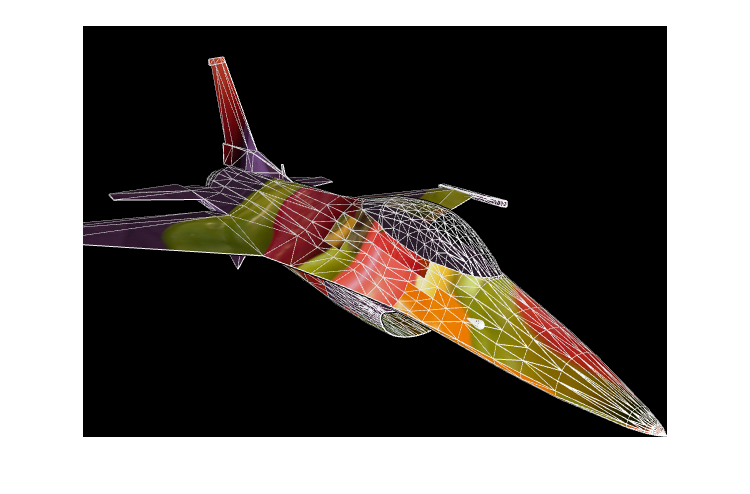

m.Normal = [];
% Same triangles and coordinates but white, unfilled and 1 step closer to the camera,
fvMesh(m,tri,xyz,[1 1 1],'DepthOffset',-1,'FillPolygons',false,'AutoCalcNormals',false);
f.Snapshot;